# **Data Analysis**

## **Load Data**

traindata = importdata('../data/traindata.txt');
X = traindata(:, 1:8);
Y = traindata(:, 9);

## Features Correlation plot

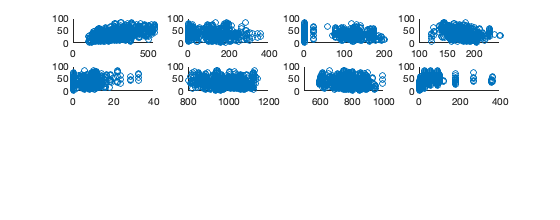

for k = 1:8
    data = rand(1,10);
    subplot(4, 4, k)
    scatter(X(:, k), Y);
end
saveas(gcf,'results/correlation_plot.png')

## Features Correlation values

corre = corrcoef(traindata);
disp(corre(9, :));

    0.4980    0.1148   -0.0983   -0.3015    0.3776   -0.1598   -0.1516    0.3364    1.0000



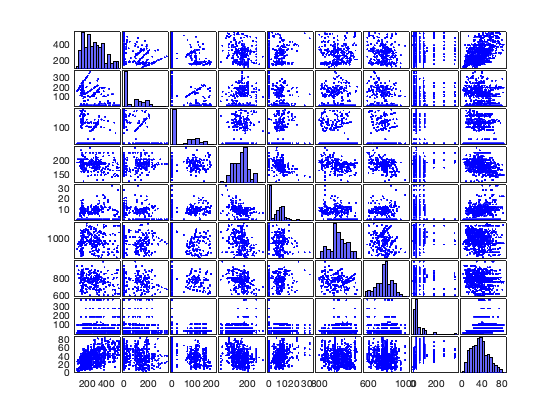

gplotmatrix(traindata);
saveas(gcf,'results/gplot_matrix.png')

## **Features Correlation values plot**

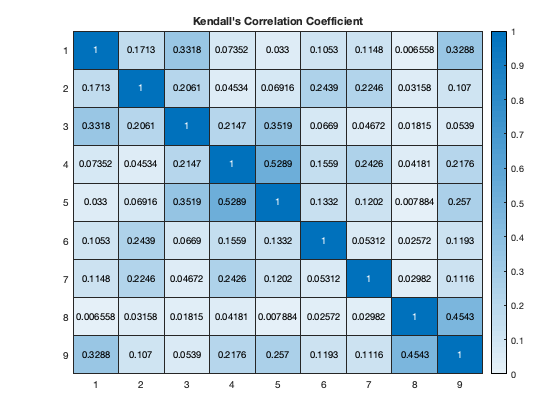

type = "Kendall";
C = corr(traindata,'type',type);
heatmap(abs(C), 'ColorLimits',[0 1],'Title', type + "'s Correlation Coefficient");
saveas(gcf,'results/kendall_correlation.png')

## PCA for visualization

mu = mean(X);
r = range(X);
X = (X - mu) ./ r;
[P, S, V] = pca(X);


### **2D Visualization**

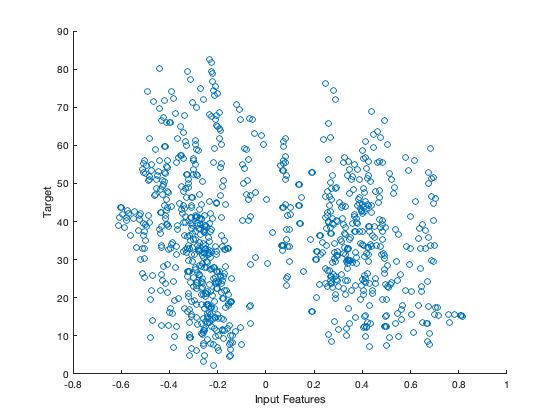

scatter(S(:, 1), Y);
xlabel('Input Features');
ylabel('Target');
saveas(gcf,'results/pca_2d.png')

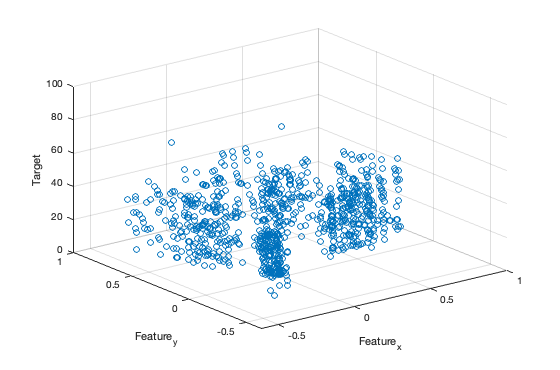

scatter3(S(:,1), S(:,2), Y);
xlabel('Feature_x');
ylabel('Feature_y');
zlabel('Target');
saveas(gcf,'results/pca_3d.png')